clear all
clc
%set variables
Model.Nx=1600;                      % number of grid points in the x (row) direction
Model.Ny=1024;                       % number of grid points in the y (column) direction
Model.dx= 3.75e-05;                % grid point spacing in the x direction [m]
Model.dy= 3.75e-05;                % grid point spacing in the y direction [m]
Model.sample_rate_model=1e9/10;        %[HZ]
Model.sample_rate_exp=1e9/5;          %[HZ]
Model.amplitude=1;
Medium.speed_of_sound=1480;           %speed of sound in a homogeneous medium should be the same as the model[m/s]
absorption_coefficient=300;%[1/m]
Medium.sound_speed_sample=1490;%speed of sound inside the sample
Medium.density_sample=1040;%density of the sample
Geometry.l=0.019;                    %diameter of transducer
Geometry.sensor_thikness=3.75e-05; %thikness of the sensor
Geometry.distance=0.02466;%distance between the back of cuvette and transducer[m].
Geometry.cuvette_length=0.0055;%Width of the sample inside the cuvette
Geometry.cuvette_face=5e-3;   %thickness of PMMA layer
Geometry.cuvette_Gasket=0.5e-3   % thickness of silicon rubber

Geometry = struct with fields:
                  l: 0.0190
    sensor_thikness: 3.7500e-05
           distance: 0.0247
     cuvette_length: 0.0055
       cuvette_face: 0.0050
     cuvette_Gasket: 5.0000e-04


Geometry.cuvette_diameter=0.018; % diameter of the sample inside the cylindrical cuvette.[m]
a=1;

%set beam profile.
Geometry.q=0.0059; %standard deviation 
Geometry.p=6;
;      % flat top factor
x_beam=-0.009:0.00001:0.009;
y_beam=exp(-((x_beam.^2)/(Geometry.q^2)).^Geometry.p);
figure(12)
plot(x_beam,y_beam)
title(['beam profile  THF=',num2str(Geometry.p),'     SD=',num2str(Geometry.q)]);
xlabel('horizontal plane [m]')
ylabel('Normalized intensity')


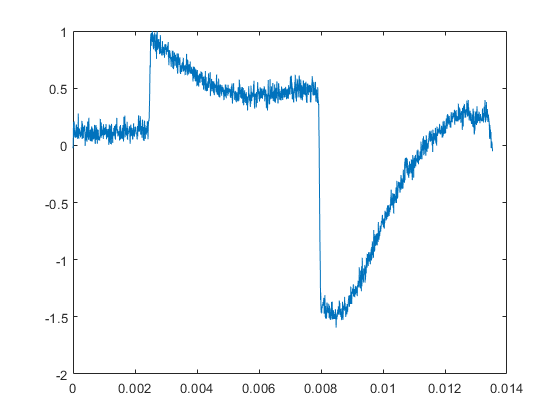

%read experimental data from TDMS files
filename = 'C:\Users\Marzieh\Documents\Marzieh\Data\18.07.2023\CUSO40.25M.18.7.2023_blue_ND0.6_test1_20230718_110507_376.tdms';;
my_tdms_struct = TDMS_getStruct(filename,1);
channels=my_tdms_struct.M670D0;
S_exp=Mean_Tdms(channels);
figure(2000)
%S_exp=smoothdata(S_exp,'movmean',5);
plot(0:1/Model.sample_rate_exp*Medium.speed_of_sound:(length(S_exp)-1)*Medium.speed_of_sound/Model.sample_rate_exp,S_exp/max(S_exp(:)))


global S_model_processed
global S_exp_processed

options = optimset('Display','iter','PlotFcns',@optimplotfval);
U=[200 1.5] ;% initial values of the parameters you need to optimize.
F=@(U)calculateRMSE(Model, Medium, Geometry,U(1),U(2));
[U,fval,exitflag,output]=fminsearchbnd(F,U,[50 0.5],[300 2],options);
%options = optimoptions(@fminsearchbnd,'Display','iter','Algorithm','quasi-newton');



%visualization
figure(1)
plot(X_model, S_model_processed);
hold on
plot(X_exp, S_exp_processed);
hold on
%plot(X_exp,fitresult(X_exp));
title(['absorption coefficient (curve fitting)=', num2str(ABCOE_curvefit),'           absorption coefficient (minimizing RMSE)=', num2str(ABCOE_fminsearch)])
ylabel('PA signal');
xlabel('X [m]');
legend('PA forward model', 'experimental');